# 01 波形の切り出しについて

 　波形の切り出しに関して以下の三種類の検証を行った。

- 波形のピークを用いた切り出し

- ノイズ信号に対するガイド波形を用いた波形の切り出し

- 時間軸方向の歪に対する（ジッタ）波形の切り出し

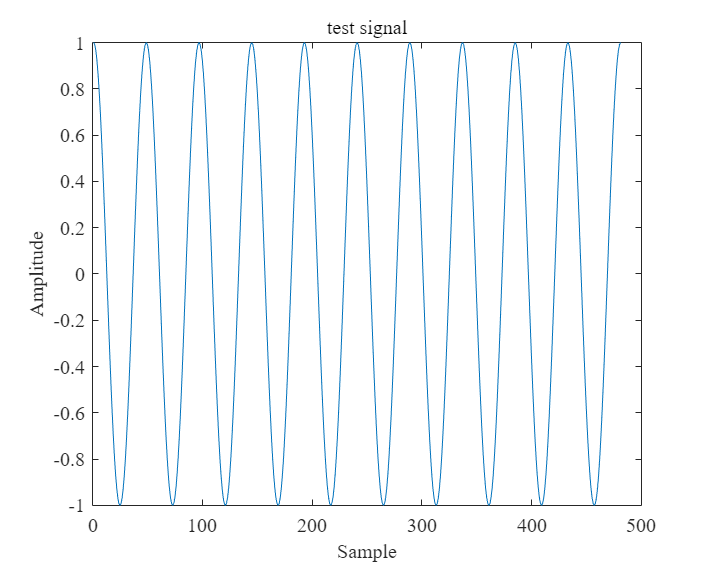

clear all

%% test 波形の作成
%パラメータ
Fs = 48e3;
f = 1000;
T = 1/f * 10;
t = 0:1/Fs:T;
vis = Visual(Fs,f);

%余弦波の作成
signal = cos(2*pi*f*t);

vis.plotSignal(signal);
title("test signal")

%% separationのインスタンス化
sep = Separation(Fs,f);

### 1. 波形のピークを用いた切り出し

    波形のピークを求めて切り出し点を決める。簡単にいうとピークピッキングを隣接サンプル間の差分から求めている。

   　-  Sepration.separateMotionを使用

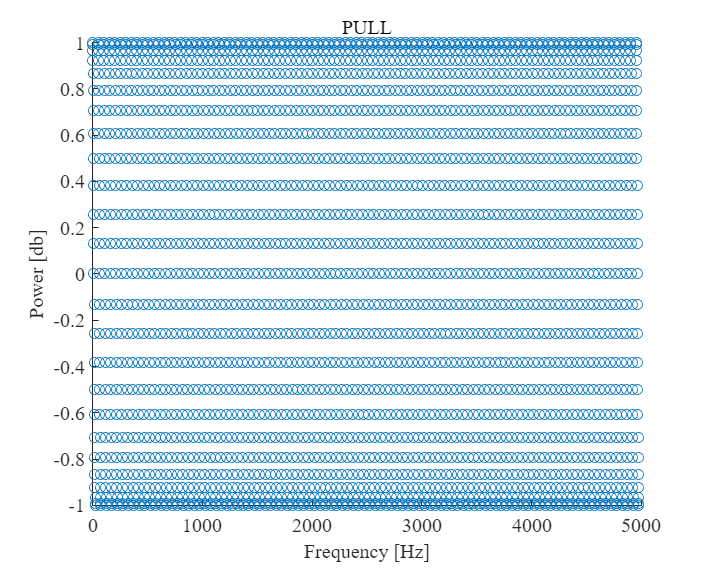

% PULL の分離
pull_signal = sep.separateMotion(signal,2);
vis.plotEachSignal(pull_signal,"PULL");

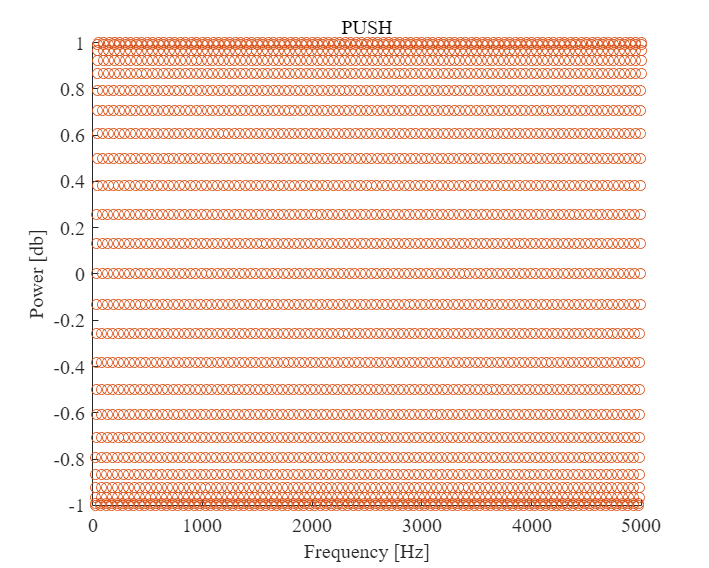

% PUSH の分離
push_signal = sep.separateMotion(signal,1);
vis.plotEachSignal(push_signal,"PUSH");

### 2. ノイズが付加された波形の切り出し

　ホワイトノイズといったガウス性のノイズが付加された場合、波形のピーク、つまり極大値を用いた方法では、音響機器由来の立ち上がり立下りの切り出しが困難になる。

そこで、ガイド波形をもちいて切り出しを行う。

    -  Sepration.separateNoiseMotionを使用

**ガウス性のノイズを持つ波形の作成**

% ノイズの作成
noise = wgn(1,length(signal),-25,'dBW');

'wgn' には Communications Toolbox が必要です。


% ノイズの付加
noise_signal = signal + noise;
vis.plotSignal(noise_signal)
title("Noise Signal")

%% Object を宣言
sepNoise = Separation(Fs,f);

**切り出しの実行**

%% Pullの切り出し
gaid = signal;
[pull, gaid_pull] = sepNoise.separateNoiseMotion(noise_signal,gaid,2);
vis.plotEachSignal(pull,"PULL")

%% Pushの切り出し
[push, gaid_push] = sepNoise.separateNoiseMotion(noise_signal,gaid,1);
vis.plotEachSignal(push,"PUSH")

### 3. 時間軸方向の歪に対する（ジッタ）波形の切り出し

  音響信号はクロックのズレやジッタの影響で時間軸方向に伸縮する。

10周期分のガイド波形を時間軸方向にスライドさせながら切り出し点を

決定することで、ロバストな分離を目指す。

    -  Sepration.separateExtendMotionを使用

%% Object を宣言
sepNoise = Separation(Fs,f);

%% Pullの切り出し
pull = sepNoise.separateExtendMotion(signal,2);

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1

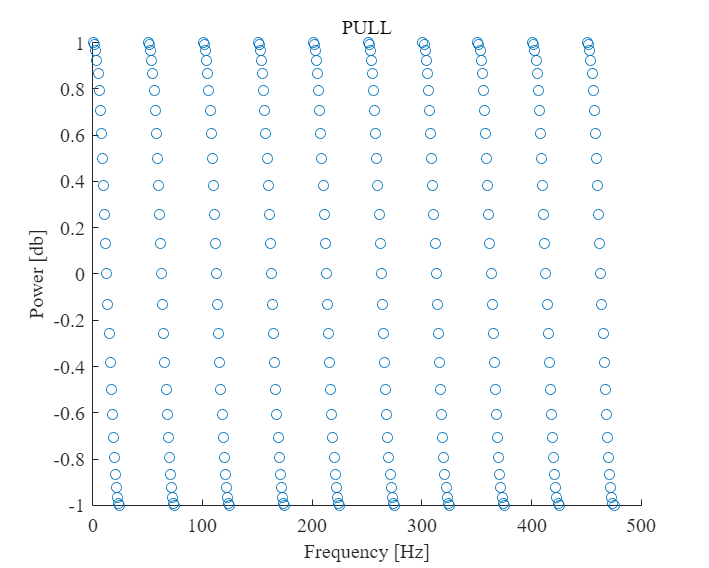

vis.plotEachSignal(pull,"PULL")


%% Pushの切り出し
[push] = sepNoise.separateExtendMotion(noise_signal,1);

関数または変数 'noise_signal' が認識されません。

vis.plotEachSignal(push,"PUSH")